clearvars; close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
addpath(genpath('D:\Profile\qse\Files\Other measurements\valerio-c60sam-epr\util'));

## Import or load

% Insert path to the data folder
chdir('D:\Profile\qse\Files\Other measurements\valerio-c60sam-epr\2023-05-12\experimental_data');
Dir.LDir = dir('*.xml');

for icw = 2:numel(Dir.LDir) % First measurement is corrupted
    [cw_(icw).x, cw_(icw).y, cw_(icw).Params] = eprload(Dir.LDir(icw).name);
    cw_(icw).Title = Dir.LDir(icw).name;
end
cw_(1) = []; % First measurement is corrupted

## Save separetely relevant PCBM data

- From 1 to 9: overmodulated spectra at different mw powers and modulation powers

- From 10 to 13: microwave power dependence

- From 14 to 19: light dependence

% Insert path where data is saved or will be saved
Dir.SPath = 'D:\Profile\qse\Files\Other measurements\valerio-c60sam-epr\2023-05-12\data_analysis\pcbm_20230512';

saveStr = input('Export PCBM data to .mat file? y/n\n', 's');
if strcmp(saveStr, 'y')
    cw = cw_(10:19);
    Title = '2023-05-12 cwEPR Valerio PCBM';
    save(Dir.SPath, 'cw', 'Title');
else
    load(Dir.SPath)
end
clear cw_; clear saveStr;

# PCBM Microwave power dependence

Shoulder on the left side!

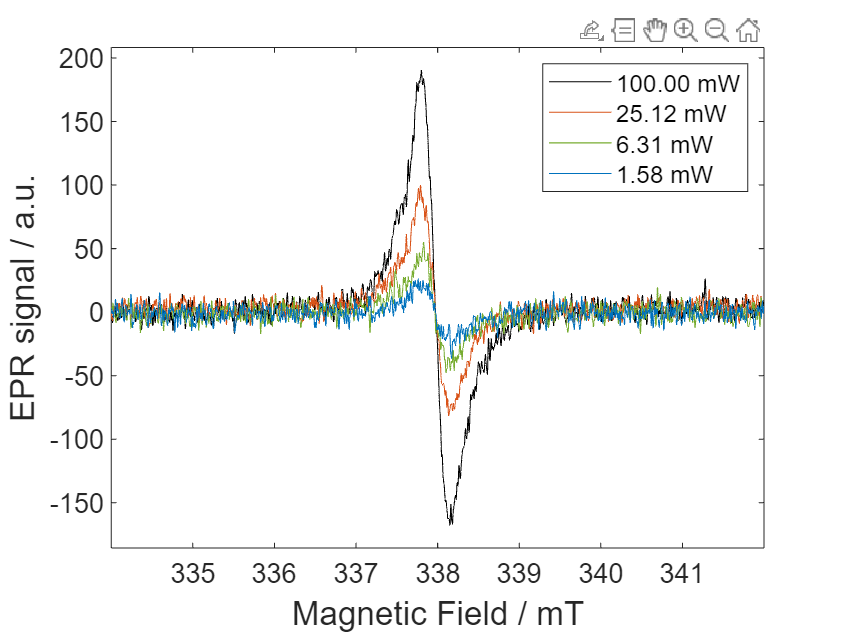

load("PlotColors.mat")
figure()
for icw = 1:4
    plot(cw(icw).x, cw(icw).y, ...
        'DisplayName', compose("%.2f mW", cw(icw).Params.MicrowavePower), ...
        'Color', PlotColors(icw))
    hold on
end
xlim(setAxLim(cw(1).x, 0));
ylim(setAxLim(cw(1).y, 0.05));
legend()
labelAxesFig(gca, 'Magnetic Field / mT', 'EPR signal / a.u.')

# Fit Microwave dependence

Sys0 = struct('g', 2.0004, ...
    'lwpp', [0. 0.24]);
Sys1 = struct('g', 2.0012, ...
    'lwpp', [0. 0.1], ...
    'weight', 0.5);

Vary0 = struct('g', 0.01, ...
    'lwpp', Sys0.lwpp);
Vary1 = struct('g', 0.02, ...
    'lwpp', Sys1.lwpp, ...
    'weight', Sys1.weight);

for icw = 1:4
    Exp.mwFreq = cw(icw).Params.MwFreq;
    Exp.Range = [min(cw(icw).x) max(cw(icw).x)];
    Exp.nPoints = numel(cw(icw).x);
    Fit(icw) = esfit(cw(icw).y, @pepper, {{Sys0, Sys1}, Exp}, {{Vary0, Vary1}});
end
Dir.SPath = 'D:\Profile\qse\Files\Other measurements\valerio-c60sam-epr\2023-05-12\data_analysis\pcbm_20230512';
save(Dir.SPath, 'cw', 'Title', 'Fit');

The simulation does not reproduce the left shoulder very well. A best SNR and/or resolution will be needed for better characterization. Anyway, even if not completely reliable, the g-values obtained are around 2.0004 and 2.0011.

# Saturation curve

Here only the total ppAmp is considered, the (supposedly) two contributions are not considered separetely.

noiseRange = [0 336; 340 1000];
for icw = 1:4
    [~, ppAmpMw(icw), sigmaNoiseMw(icw)] = getSNR(cw(icw).x, cw(icw).y, noiseRange);
    mwPower(icw) = cw(icw).Params.MicrowavePower;
end

Linear behavior in this microwave range. Should check on the ESP580 for larger microwave power range.

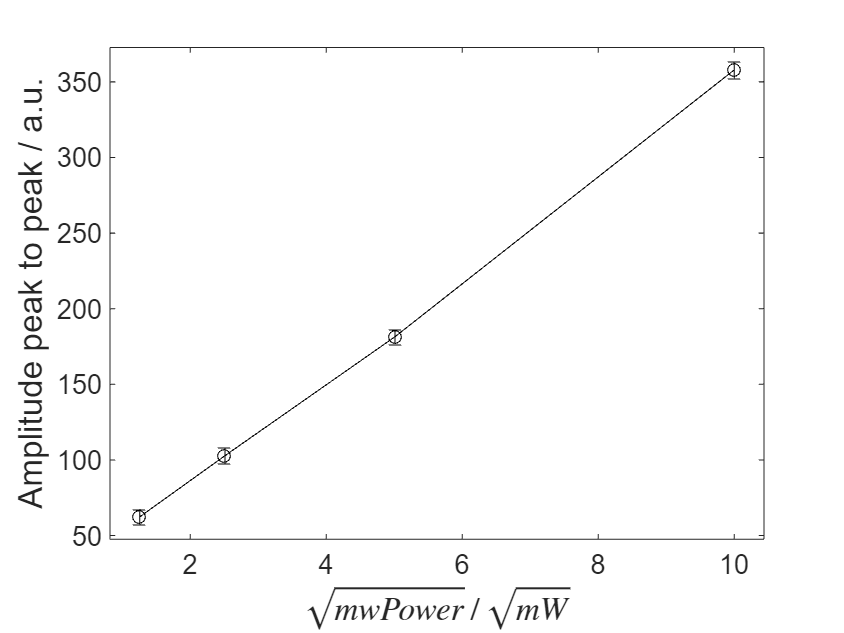

figure()
errorbar(sqrt(mwPower), ppAmpMw, sigmaNoiseMw, 'ko-')
xlim(setAxLim(sqrt(mwPower), 0.05));
ylim(setAxLim(ppAmpMw, 0.05));
labelAxesFig(gca, '$\sqrt{mwPower} / \sqrt{mW}$', 'Amplitude peak to peak / a.u.')

# PCBM Light dependence

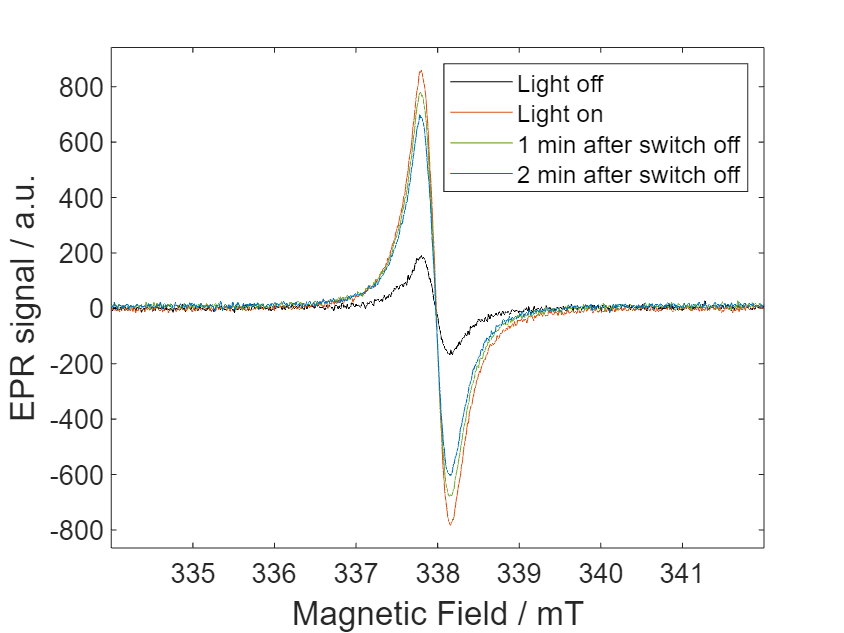

figure()
iColor = 1;
for icw = [1, 8:10]
    if icw > 1; iColor = icw - 6; end
    plot(cw(icw).x, cw(icw).y, 'Color', PlotColors(iColor))
    hold on
end
legend('Light off', 'Light on', '1 min after switch off', '2 min after switch off')
xlim(setAxLim(cw(8).x, 0));
ylim(setAxLim(cw(8).y, 0.05));
labelAxesFig(gca, 'Magnetic Field / mT', 'EPR signal / a.u.')

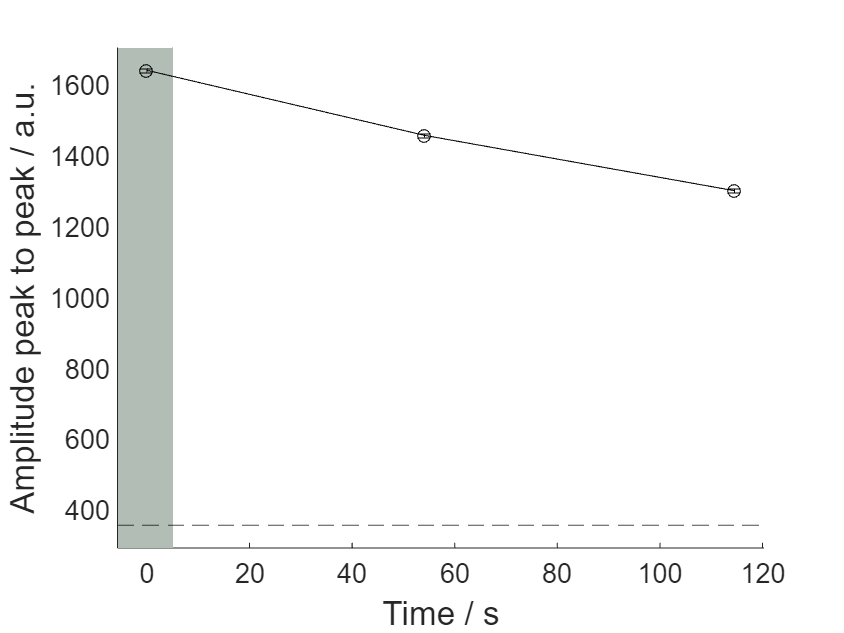

ipp = 1;
for icw = [1, 8:10]
    if icw > 1; ipp = icw - 6; end
    [~, ppAmpL(ipp), sigmaNoiseL(ipp)] = getSNR(cw(icw).x, cw(icw).y, noiseRange);
    timeStamp(ipp) = datetime(strrep(cw(icw).Params.Timestamp(1:23), 'T', ' '));
end
xTime = convertTo(timeStamp, 'excel') - convertTo(timeStamp(2), 'excel');
xTime = xTime*24*60*60; % seconds

figure()
rectangle('Position', [-200, 0, 205, 2000], ...
    'FaceColor', PlotColors(end), ...
    'EdgeColor', PlotColors(end)); % Light on
hold on
errorbar(xTime(2:end), ppAmpL(2:end), sigmaNoiseL(2:end), 'ko-')
yline(ppAmpL(1), 'k--') % ppAmp in the dark
xlim(setAxLim(xTime(2:end), 0.05));
ylim(setAxLim(ppAmpL, 0.05));
labelAxesFig(gca, 'Time / s', 'Amplitude peak to peak / a.u.')